# **FDS 2024: Field and service robotics**

## `Homework 2 Question 3 and 4`

## Andrea Morghen

`Question 3`

Let's define some usefull parameter

clc
clear all

qi = [0 0 0];
qf = rand(1,3);
qf = qf/norm(qf); % normalization of qf
qf= [0.563251318410320	0.682189313334158	0.466224938288061]

qf =     0.5633    0.6822    0.4662


t = 2; %first guess for the time
k=1; %the value of k is fixed
fs = 20 %number of sample for in every second

fs = 20


alpha_x= k *cos(qf(3)) - 3*qf(1)

alpha_x = -0.7965

alpha_y= k *sin(qf(3)) - 3*qf(2)

alpha_y = -1.5971

beta_x= k *cos(qi(3)) + 3*qi(1)

beta_x = 1

beta_y= k *sin(qi(3)) + 3*qi(2)

beta_y = 0

To calculate the s, a matlab function Trapezoidal profile was created, which as can be guessed from the name produces an s function with a trapezoidal velocity profile. Then x, y, x_first_dot, y_first_dot, x_first_ddot, y_first_ddot and theta are calculated using the cubic Cartesian polynomial method. (The first and second derivative functions were obtained by symbolic derivation from x and y).

[s,s_dot,s_dotdot] = trap_profile(0, t, fs, qi, qf); 

x = s.^3.*qf(1) - (s-1).^3.*qi(1) + alpha_x.*s.^2.*(s-1) + beta_x.*s.*(s-1).^2;
y = s.^3.*qf(2) - (s-1).^3.*qi(2) + alpha_y.*s.^2.*(s-1) + beta_y.*s.*(s-1).^2;


x_first_dot = 3.*s.^2.*qf(1) - 3.*(s-1).^2.*qi(1) + alpha_x.*s.*(3.*s-2) + beta_x.*(3.*s-1).*(s-1);
y_first_dot = 3.*s.^2.*qf(2) - 3.*(s-1).^2.*qi(2) + alpha_y.*s.*(3.*s-2) + beta_y.*(3.*s-1).*(s-1);

x_first_ddot = 6.*s.*qf(1) - 6.*(s-1).*qi(1) + alpha_x.*(6.*s-2) + beta_x.*(6.*s-4);
y_first_ddot = 6.*s.*qf(2) - 6.*(s-1).*qi(2) + alpha_y.*(6.*s-2) + beta_y.*(6.*s-4);

theta=atan2(y_first_dot,x_first_dot);

To get the real x_dot, y_dot you have to multiply x_first_dot and y_first_dot respectively by s_dot

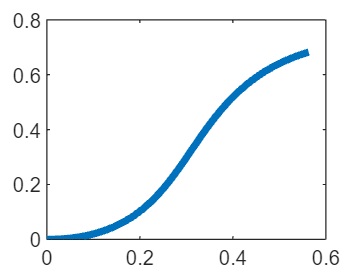

time = 0:1/fs:t-1/fs;
plot(x,y,'LineWidth',3)

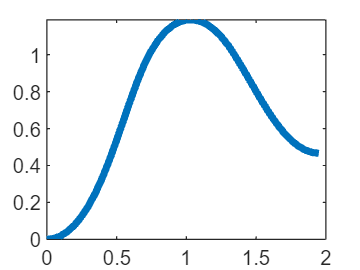

plot(time,theta,'LineWidth',3)

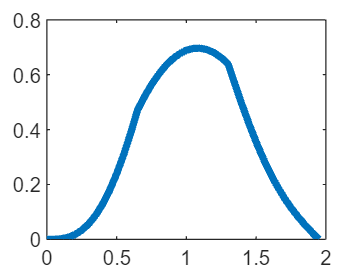

plot(time,y_first_dot.*s_dot,'LineWidth',3)

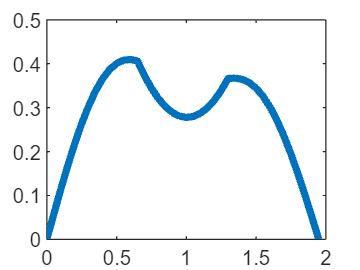

plot(time,x_first_dot.*s_dot,'LineWidth',3)

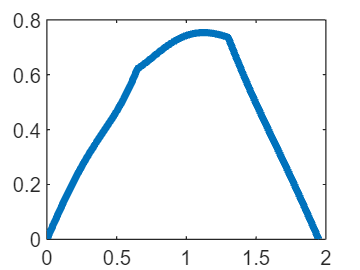




v = sqrt(x_first_dot.^2 + y_first_dot.^2) .* s_dot;
w = (y_first_ddot.*x_first_dot - x_first_ddot.*y_first_dot)./(x_first_dot.^2 + y_first_dot.^2) .* s_dot;
plot(time,v,'LineWidth',3)

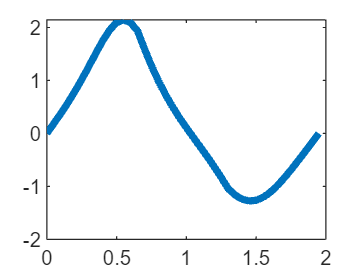

plot(time,w,'LineWidth',3)

Let's see if the speed limits are exceeded. If it is the case recompute the time law with a different time scale.

max(v)

ans = 0.7533

max(w)

ans = 2.1449


if (max(v)>2 || max(w)>1)
    disp('velocity bounds exceeded, recomputation of the time low')
    T=max(max(v)/2,max(w)/1)
    t=ceil(t*T)
    [s,s_dot,s_dotdot] = trap_profile(0, t, fs, qi, qf); 
    
    x = s.^3.*qf(1) - (s-1).^3.*qi(1) + alpha_x.*s.^2.*(s-1) + beta_x.*s.*(s-1).^2;
    y = s.^3.*qf(2) - (s-1).^3.*qi(2) + alpha_y.*s.^2.*(s-1) + beta_y.*s.*(s-1).^2;


    x_first_dot = 3.*s.^2.*qf(1) - 3.*(s-1).^2.*qi(1) + alpha_x.*s.*(3.*s-2) + beta_x.*(3.*s-1).*(s-1);
    y_first_dot = 3.*s.^2.*qf(2) - 3.*(s-1).^2.*qi(2) + alpha_y.*s.*(3.*s-2) + beta_y.*(3.*s-1).*(s-1);

    x_first_ddot = 6.*s.*qf(1) - 6.*(s-1).*qi(1) + alpha_x.*(6.*s-2) + beta_x.*(6.*s-4);
    y_first_ddot = 6.*s.*qf(2) - 6.*(s-1).*qi(2) + alpha_y.*(6.*s-2) + beta_y.*(6.*s-4);

    theta=atan2(y_first_dot,x_first_dot);

    v = sqrt(x_first_dot.^2 + y_first_dot.^2) .* s_dot;
    w = (y_first_ddot.*x_first_dot - x_first_ddot.*y_first_dot)./(x_first_dot.^2 + y_first_dot.^2) .* s_dot;

    disp(['velocity bounds restored, final time is ', num2str(t)])   
    time = 0:1/fs:t-1/fs;
end

velocity bounds exceeded, recomputation of the time low


T = 2.1449

t = 5

velocity bounds restored, final time is 5


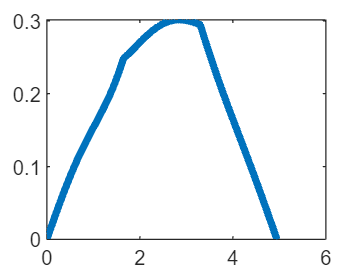


plot(time,v,'LineWidth',3)

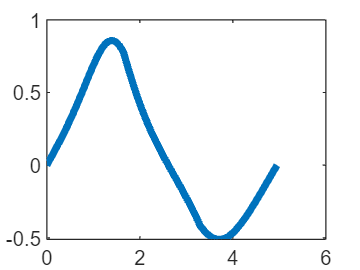

plot(time,w,'LineWidth',3)

max(v)

ans = 0.3015

max(w)

ans = 0.8579

`Question 4`

Let's define parameter needed for the simulink model.

b = 0.05;
k1 = 5;
k2 = 5;
y1_des = x + b.*cos(theta);
y2_des = y + b.*sin(theta);
y1_dot_des = cos(theta).*v - b.*sin(theta).*w;
y2_dot_des = sin(theta).*v + b.*cos(theta).*w;

x_des = timeseries(x);
y_des = timeseries(y);
y1_des = timeseries(y1_des);
y2_des =  timeseries(y2_des);
y1_dot_des = timeseries(y1_dot_des);
y2_dot_des = timeseries(y2_dot_des);
